# Mathworks Quadcopter Structural Analysis Project

%{

This program analyzes the shear and moment in each drone arm based on the
payload, weight, and dimensions of the drone.


%}

clc; 
clear;


## Dimensions, Paramenters (Mass of Drone, Payload, etc.) 

% Dimensions and constants used for calculations

gravity = 9.81; % acceleration due to gravity in m/s^2

densityCarbonFiber = 1420; % density of carbon fiber in kg/m^3

droneMass = 1.56; % mass of drone frame and components in kg

motorMass = 0.046 + 0.015; % Mass of motor in kg

payloadMass = 2.454; % mass of payload in kg

maxThrust = 9.395/gravity; % maximum thrust in kg

armWidth = 0.035; % arm width in meters

armThickness = 0.00635; % arm thickness in meters including the mounting

% ARM TYPE 1

armLengthOne = 0.145; % length of arm type 1 in meters

lengthMotorOne =  0.127; % length to motor center of mass

% ARM TYPE 2
armLengthTwo = 0.134; % length of arm type 2 in meters

lengthMotorTwo = 0.117; % length to motor center of mass


## Calculations

armVolumeOne = armWidth * armLengthOne * armThickness; % volume of drone arm type one in m^3 

w_One = armVolumeOne * densityCarbonFiber * gravity / armLengthOne; % distributed load caused my the mass of the arm in kg/m

armVolumeTwo = armWidth * armLengthTwo * armThickness; % volume of drone arm type two in m^3 

w_Two = armVolumeTwo * densityCarbonFiber * gravity /armLengthTwo; % distributed load caused my the mass of the arm in kg/m

thrustMax = 4 * gravity; % max thrust from all 4 motors combined in Newtons

F_Thrust = maxThrust * gravity; % max force from thrust in N

F_motor_mass = motorMass * gravity; % force on arm from motor mass

F_body_payload = gravity * (droneMass + payloadMass) / 4; % force from body of motor on arm

F_mount_one = - F_Thrust + w_One * armLengthOne + F_motor_mass + F_body_payload; % Reaction Force at the mount for arm type one

F_mount_two = - F_Thrust + w_Two * armLengthOne + F_motor_mass + F_body_payload; % Reaction Force at the mount for arm type two

M_mount_one = (0.5 * w_One * armLengthOne ^ 2) + lengthMotorOne * (- F_Thrust + F_motor_mass); % moment reaction at the mounting end for arm type one

M_mount_two = (0.5 * w_Two * armLengthOne ^ 2) + lengthMotorTwo * (- F_Thrust + F_motor_mass); % moment reaction at the mounting end for arm type two


## Shear and Moment Calculations Arm Type 1

% two arrays of position values for both sections along the arm
x1 = linspace(0, lengthMotorOne, 500);         % from base to motor center
x2 = linspace(lengthMotorOne, armLengthOne, 500); % from motor to tip

% shear equation from 0 < x < lengthMotor
V_x1 = F_mount_one - F_body_payload - w_One * x1; % units: Pa

% shear equation from lengthMotor lengthMotor < x < armLength
V_x2 = F_mount_one - F_body_payload - w_One * x2 - F_motor_mass + F_Thrust;  % units: Pa

% moment equation from 0 < x < lengthMotor
M_x1 = -(0.5 * w_One * x1 .^ 2) + (F_mount_one - F_body_payload) * x1 - M_mount_one; % units: Nm   

% moment equation from lengthMotor < x < armLength
M_x2 = (x2 - lengthMotorOne) * (F_Thrust - F_motor_mass) - M_mount_one + (F_mount_one-F_body_payload) * x2 -0.5 * w_One * x2 .^ 2; % units: Nm   



## Shear and Moment Calculations Arm Type 2

% two arrays of position values for both sections along the arm
x11 = linspace(0, lengthMotorTwo, 500);         % from base to motor center
x22 = linspace(lengthMotorTwo,armLengthTwo, 500); % from motor to tip

% shear equation from 0 < x < lengthMotor
V_x11 = F_mount_two - F_body_payload - w_Two * x11; % units: Pa

% shear equation from lengthMotor lengthMotor < x < armLength
V_x22 = F_mount_two - F_body_payload - w_Two * x22 - F_motor_mass + F_Thrust;  % units: Pa

% moment equation from 0 < x < lengthMotor
M_x11 = -(0.5 * w_Two * x11 .^ 2) + (F_mount_two - F_body_payload) * x11 - M_mount_two; % units: Nm   

% moment equation from lengthMotor < x < armLength
M_x22 = (x22 - lengthMotorTwo) * (F_Thrust - F_motor_mass) - M_mount_two + (F_mount_one-F_body_payload) * x22 -0.5 * w_Two * x22 .^ 2; % units: Nm   


## Plot of Shear and Moment Along the Arms

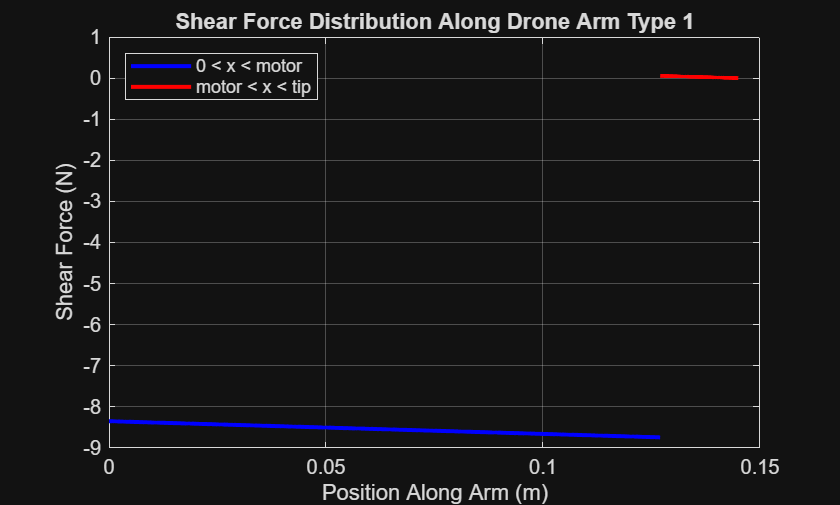

% Shear Along Drone Arm Type 1
figure (1);
plot(x1, V_x1, 'b', 'LineWidth', 2); hold on;
plot(x2, V_x2, 'r', 'LineWidth', 2);
xlabel('Position Along Arm (m)');
ylabel('Shear Force (N)');
title('Shear Force Distribution Along Drone Arm Type 1');
legend('0 < x < motor', 'motor < x < tip', location = 'northwest');
grid on;
hold off;

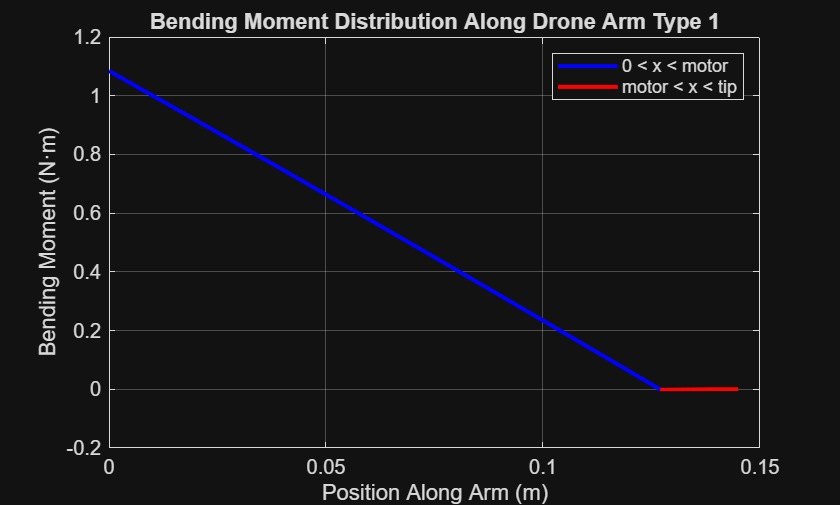


% Moment Along Drone Arm Type 1
figure (2);
plot(x1, M_x1, 'b', 'LineWidth', 2); hold on;
plot(x2, M_x2, 'r', 'LineWidth', 2);
xlabel('Position Along Arm (m)');
ylabel('Bending Moment (N·m)');
title('Bending Moment Distribution Along Drone Arm Type 1');
legend('0 < x < motor', 'motor < x < tip', location = 'northeast');
grid on;
hold off;

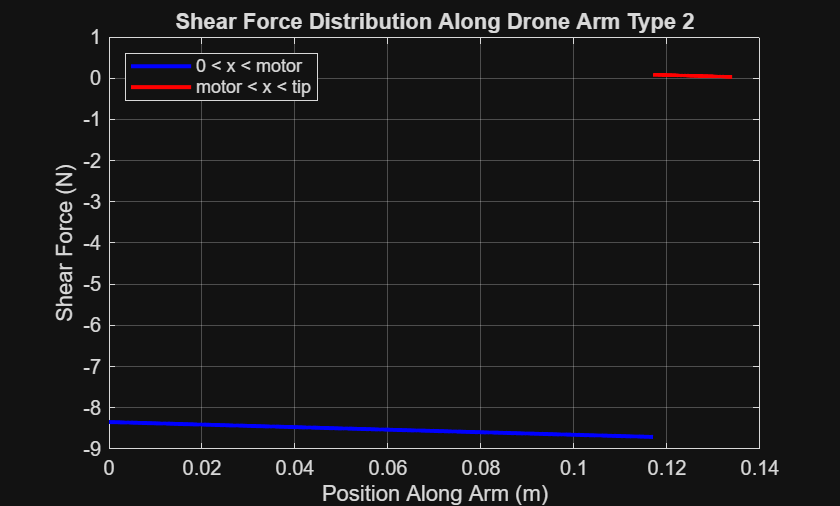


% Shear Along Drone Arm Type 2
figure (3);
plot(x11, V_x11, 'b', 'LineWidth', 2); hold on;
plot(x22, V_x22, 'r', 'LineWidth', 2);
xlabel('Position Along Arm (m)');
ylabel('Shear Force (N)');
title('Shear Force Distribution Along Drone Arm Type 2');
legend('0 < x < motor', 'motor < x < tip', location = 'northwest');
grid on;
hold off

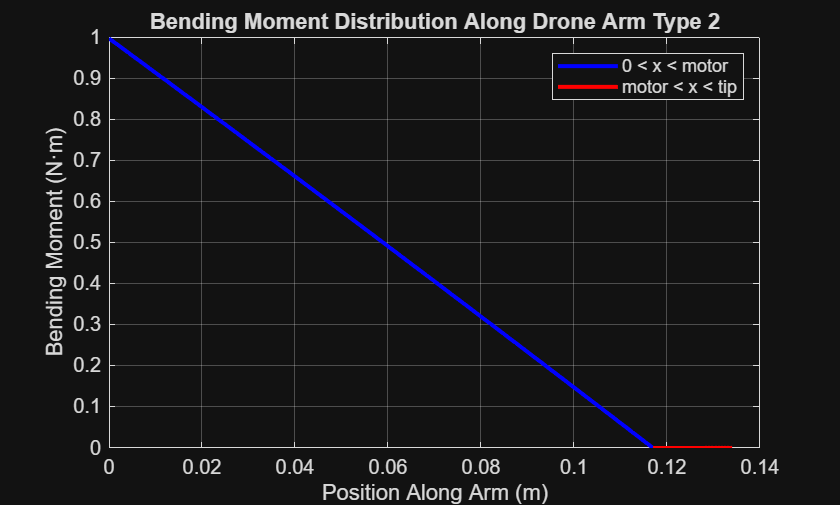


% Moment Along Drone Arm Type 2
figure (4);
plot(x11, M_x11, 'b', 'LineWidth', 2); hold on;
plot(x22, M_x22, 'r', 'LineWidth', 2);
xlabel('Position Along Arm (m)');
ylabel('Bending Moment (N·m)');
title('Bending Moment Distribution Along Drone Arm Type 2');
legend('0 < x < motor', 'motor < x < tip', location = 'northeast');
grid on;